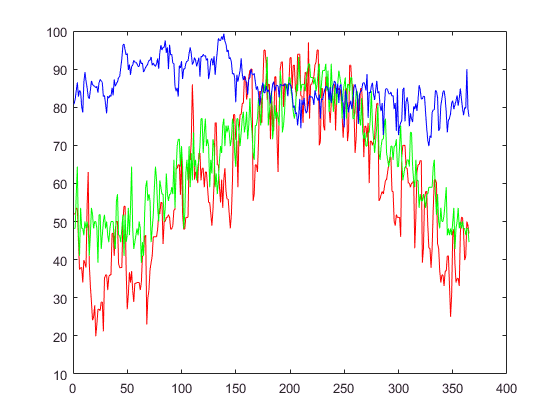

load bostonTemps2005.mat
load tokyoTemps2005.mat
load bangaloreTemps2005.mat

plot(boston_data(:,1),'r')
hold on
plot(tokyo_data(:,1),'g')
plot(bangalore_data(:,1),'b')



L = length(boston_data)

L = 365


bostm = mean(boston_data(:,1))

bostm = 60.7118

tokyom = mean(tokyo_data(:,1))

tokyom = 66.2493

bangm = mean(bangalore_data(:,1))

bangm = 85.4841


movbost = movmean(boston_data(:,1),50,...
    'EndPoints','discard');

Error using movmean
Invalid option combination. Option must be 'omitnan' or 'includenan'.


plot([1 L], [bostm bostm], 'r:')
plot([1 L], [tokyom tokyom], 'g:')
plot([1 L], [bangm bangm], 'b:')

plot(movbost,'k--')

hold off
xlabel('day')
ylabel('City Temps \circ F')
templabel = ['City Temps ', 176, 'F']
ylabel(templabel)
legend('boston','tokyo','bangalore','location','eastoutside')


